**IMU data analysis**

clear all; 
close all; 
clc;

% Read the csv files with the data already converted according to the
% scale factor and sensitivity of both Accelerometer and Gyroscope
data1 = readtable('IMU_Ida_22_05.csv', 'ReadVariableNames', false);
data2 = readtable('IMU_Zia_20_05_1.csv', 'ReadVariableNames', false);

Define time points for the three phases each one lasting 10 sec

phase1_start = 0; % Start of first phase (Quiet Standing)
phase2_start = 10; % Start of second phase (Walking)
phase3_start = 20; % Start of third phase (Standing and Sitting)

fs_Hz = 100; % Sampling frequency

g_m_s2 = 9.81; % Gravitational acceleration

**Subject 1: Ida**

% Linear Acceleration (g)
ax1 = data1.Var1 * g_m_s2; % times g_m_s2 to obtain the accelerations in m/s^2
ay1 = data1.Var2 * g_m_s2;
az1 = data1.Var3 * g_m_s2;

% Angular Acceleration (deg/s)
gx1 = data1.Var4;
gy1 = data1.Var5;
gz1 = data1.Var6;

**Subject 2:Letizia**

% Linear Acceleration (g)
ax2 = data2.Var1 * g_m_s2;
ay2 = data2.Var2 * g_m_s2;
az2 = data2.Var3 * g_m_s2;

% Angular Acceleration (deg/s)
gx2 = data2.Var4;
gy2 = data2.Var5;
gz2 = data2.Var6;


Ensure that both datasets have the same length to be compared with each other.

min_length = min([length(ax1), length(ax2)]);
ax1 = ax1(1:min_length);
ay1 = ay1(1:min_length);
az1 = az1(1:min_length);
gx1 = gx1(1:min_length);
gy1 = gy1(1:min_length);
gz1 = gz1(1:min_length);

ax2 = ax2(1:min_length);
ay2 = ay2(1:min_length);
az2 = az2(1:min_length);
gx2 = gx2(1:min_length);
gy2 = gy2(1:min_length);
gz2 = gz2(1:min_length);

dt = 1/fs_Hz; % sample interval

% Define time vector assuming data is sampled at a uniform rate
time = (0:min_length-1) / fs_Hz;

**Linear Acceleration Plot**

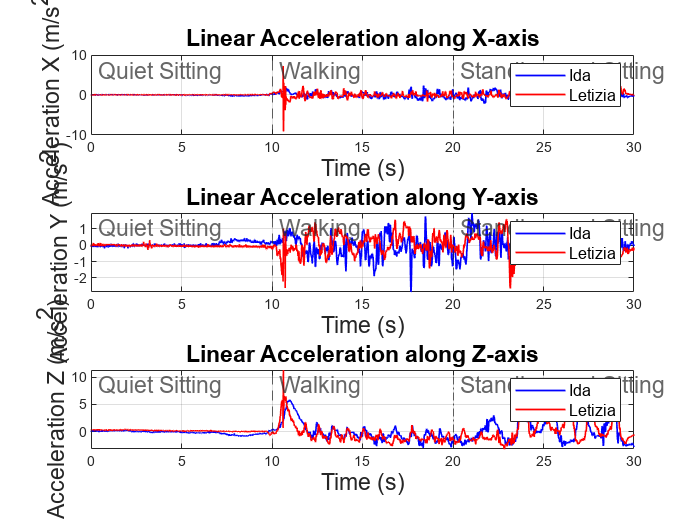

font_size = 14;
figure;
subplot(3,1,1);
plot(time, detrend(ax1), 'b', 'DisplayName', 'Ida', 'LineWidth', 1);
hold on;
plot(time, detrend(ax2), 'r', 'DisplayName', 'Letizia', 'LineWidth', 1);
title('Linear Acceleration along X-axis', 'FontSize', font_size);
xlabel('Time (s)', 'FontSize', font_size);
ylabel('Acceleration X (m/s^2)', 'FontSize', font_size);
legend('FontSize', 10);
grid on;

% Add vertical lines to separate phases
xline(phase1_start, '-', {'Quiet Sitting'},'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase2_start, '--', {'Walking'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase3_start, '-.', {'Standing and Sitting'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');

subplot(3,1,2);
plot(time, detrend(ay1), 'b', 'DisplayName', 'Ida', 'LineWidth', 1);
hold on;
plot(time, detrend(ay2), 'r', 'DisplayName', 'Letizia', 'LineWidth', 1);
title('Linear Acceleration along Y-axis', 'FontSize', font_size);
xlabel('Time (s)', 'FontSize', font_size);
ylabel('Acceleration Y (m/s^2)', 'FontSize', font_size);
legend('FontSize', 10);
grid on;

% Add vertical lines to separate phases
xline(phase1_start, '-', {'Quiet Sitting'},'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase2_start, '--', {'Walking'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase3_start, '-.', {'Standing and Sitting'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');

subplot(3,1,3);
plot(time, detrend(az1), 'b', 'DisplayName', 'Ida', 'LineWidth', 1);
hold on;
plot(time, detrend(az2), 'r', 'DisplayName', 'Letizia', 'LineWidth', 1);
title('Linear Acceleration along Z-axis', 'FontSize', font_size);
xlabel('Time (s)', 'FontSize', font_size);
ylabel('Acceleration Z (m/s^2)', 'FontSize', font_size);
legend('FontSize', 10);
grid on;

% Add vertical lines to separate phases
xline(phase1_start, '-', {'Quiet Sitting'},'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase2_start, '--', {'Walking'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase3_start, '-.', {'Standing and Sitting'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');

**Angular Velocity Plot**

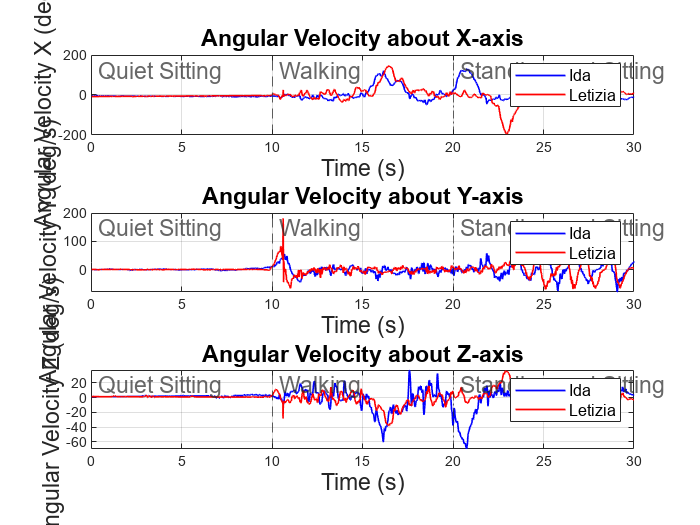

figure;
subplot(3,1,1);
plot(time, detrend(gx1), 'b', 'DisplayName', 'Ida', 'LineWidth', 1);
hold on;
plot(time, detrend(gx2), 'r', 'DisplayName', 'Letizia', 'LineWidth', 1);
title('Angular Velocity about X-axis', 'FontSize', font_size);
xlabel('Time (s)','FontSize', font_size);
ylabel('Angular Velocity X (deg/s)', 'FontSize', font_size);
legend('FontSize', 10);
grid on;

xline(phase1_start, '-', {'Quiet Sitting'},'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase2_start, '--', {'Walking'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase3_start, '-.', {'Standing and Sitting'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');

subplot(3,1,2);
plot(time, detrend(gy1), 'b', 'DisplayName', 'Ida', 'LineWidth', 1);
hold on;
plot(time, detrend(gy2), 'r', 'DisplayName', 'Letizia', 'LineWidth', 1);
title('Angular Velocity about Y-axis', 'FontSize', font_size);
xlabel('Time (s)', 'FontSize', font_size);
ylabel('Angular Velocity Y (deg/s)', 'FontSize', font_size);
legend('FontSize', 10);
grid on;

xline(phase1_start, '-', {'Quiet Sitting'},'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase2_start, '--', {'Walking'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase3_start, '-.', {'Standing and Sitting'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');

subplot(3,1,3);
plot(time, detrend(gz1), 'b', 'DisplayName', 'Ida', 'LineWidth', 1);
hold on;
plot(time, detrend(gz2), 'r', 'DisplayName', 'Letizia', 'LineWidth', 1);
title('Angular Velocity about Z-axis', 'FontSize', font_size);
xlabel('Time (s)', 'FontSize', font_size);
ylabel('Angular Velocity Z (deg/s)', 'FontSize', font_size);
legend('FontSize', 10);
grid on;

xline(phase1_start, '-', {'Quiet Sitting'},'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase2_start, '--', {'Walking'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase3_start, '-.', {'Standing and Sitting'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');

**Average amplitude and frequency for each signal**

[ax1_amp, ax1_freq] = analyze_signal(ax1, fs_Hz);
[ay1_amp, ay1_freq] = analyze_signal(ay1, fs_Hz);
[az1_amp, az1_freq] = analyze_signal(az1, fs_Hz);
[gx1_amp, gx1_freq] = analyze_signal(gx1, fs_Hz);
[gy1_amp, gy1_freq] = analyze_signal(gy1, fs_Hz);
[gz1_amp, gz1_freq] = analyze_signal(gz1, fs_Hz);

[ax2_amp, ax2_freq] = analyze_signal(ax2, fs_Hz);
[ay2_amp, ay2_freq] = analyze_signal(ay2, fs_Hz);
[az2_amp, az2_freq] = analyze_signal(az2, fs_Hz);
[gx2_amp, gx2_freq] = analyze_signal(gx2, fs_Hz);
[gy2_amp, gy2_freq] = analyze_signal(gy2, fs_Hz);
[gz2_amp, gz2_freq] = analyze_signal(gz2, fs_Hz);

Results

% Create a single table for both Ida and Camilla
ComparisonTable_LinAcc = table({'ax'; 'ay'; 'az'}, ...
    [ax1_amp; ay1_amp; az1_amp], ...
    [ax1_freq; ay1_freq; az1_freq], ...
    [ax2_amp; ay2_amp; az2_amp], ...
    [ax2_freq; ay2_freq; az2_freq], ...
    'VariableNames', {'LinAcc', 'Ida_Average_Amplitude_m_s2', 'Ida_Frequency_Hz', 'Letizia_Average_Amplitude_m_s2', 'Letizia_Frequency_Hz'});

ComparisonTable_AngVel = table({'gx'; 'gy'; 'gz'}, ...
    [gx1_amp; gy1_amp; gz1_amp], ...
    [gx1_freq; gy1_freq; gz1_freq], ...
    [gx2_amp; gy2_amp; gz2_amp], ...
    [gx2_freq; gy2_freq; gz2_freq], ...
    'VariableNames', {'AngVel', 'Ida_Average_Amplitude_deg_s', 'Ida_Frequency_Hz', 'Letizia_Average_Amplitude_deg_s', 'Letizia_Frequency_Hz'});
disp(ComparisonTable_LinAcc);

    LinAcc    Ida_Average_Amplitude_m_s2    Ida_Frequency_Hz    Letizia_Average_Amplitude_m_s2    Letizia_Frequency_Hz
    ______    __________________________    ________________    ______________________________    ____________________

    {'ax'}             0.43785                    1.1663                   0.43184                       0.39987      
    {'ay'}             0.34322                  0.066644                   0.30987                       0.56648      
    {'az'}              1.0472                  0.066644                    1.0561                      0.066644      



disp(ComparisonTable_AngVel);

    AngVel    Ida_Average_Amplitude_deg_s    Ida_Frequency_Hz    Letizia_Average_Amplitude_deg_s    Letizia_Frequency_Hz
    ______    ___________________________    ________________    _______________________________    ____________________

    {'gx'}              19.105                   0.19993                     18.367                       0.099967      
    {'gy'}              11.817                   0.63312                     12.213                        0.76641      
    {'gz'}              8.3692                   0.19993                     4.7419                       0.099967      



**RPY angles**

Subject 1: Ida

% Angles initialization
roll_gyro1 = zeros(length(gx1), 1);
pitch_gyro1 = zeros(length(gy1), 1);
yaw_gyro1 = zeros(length(gz1), 1);

% Numerical integration 
for i = 2:length(gx1)
    roll_gyro1(i) = roll_gyro1(i-1) + gx1(i) * dt;
    pitch_gyro1(i) = pitch_gyro1(i-1) + gy1(i) * dt;
    yaw_gyro1(i) = yaw_gyro1(i-1) + gz1(i) * dt;
end

% Angles computation from accelerometers 
roll_acc1 = atan2(ay1, az1); % about z
pitch_acc1 = atan2(-ax1, ay1.*sin(roll_acc1) + az1.*cos(roll_acc1)); % about y
% Data Fusion with Complementary Filter
alpha = 0.98; % Complementary Filter Weight 
roll1 = alpha * roll_gyro1 + (1 - alpha) * rad2deg(roll_acc1);
pitch1 = alpha * pitch_gyro1 + (1 - alpha) * rad2deg(pitch_acc1);
yaw1 = yaw_gyro1; % Yaw only from gyro


Subject 2: Letizia

% Angles initialization
roll_gyro2 = zeros(length(gx2), 1);
pitch_gyro2 = zeros(length(gy2), 1);
yaw_gyro2 = zeros(length(gz2), 1);

% Numerical integration 
for i = 2:length(gx2)
    roll_gyro2(i) = roll_gyro2(i-1) + gx2(i) * dt;
    pitch_gyro2(i) = pitch_gyro2(i-1) + gy2(i) * dt;
    yaw_gyro2(i) = yaw_gyro2(i-1) + gz2(i) * dt;
end

% Angles computation from accelerometers 
roll_acc2 = atan2(ay2,  az2);
pitch_acc2 = atan2(-ax2, ay2.*sin(roll_acc2) + az2.*cos(roll_acc2));

% Data Fusion with Complementary Filter
alpha = 0.98; % Complementary Filter Weight 
roll2 = alpha * roll_gyro2 + (1 - alpha) * rad2deg(roll_acc2);
pitch2 = alpha * pitch_gyro2 + (1 - alpha) * rad2deg(pitch_acc2);
yaw2 = yaw_gyro2; % Yaw only from gyro

time = (0:length(roll1)-1) * dt;

**Roll, Pitch, Yaw Plot**

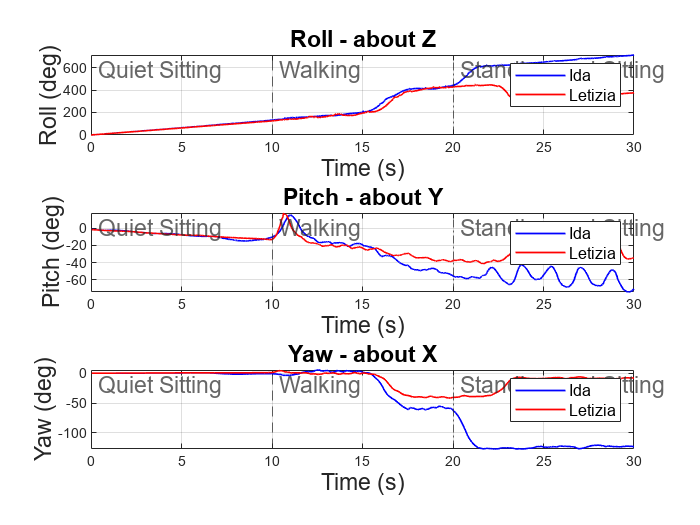

figure;

% Plot for Roll
subplot(3,1,1);
plot(time, roll1, 'b', 'DisplayName', 'Ida', 'LineWidth', 1);
title('Roll - about Z', 'FontSize', font_size);
xlabel('Time (s)', 'FontSize', font_size);
ylabel('Roll (deg)', 'FontSize', font_size)
hold on;
plot(time, roll2, 'r', 'DisplayName', 'Letizia', 'LineWidth', 1);
grid on;
legend('FontSize', 10);

% Add vertical lines to separate phases
xline(phase1_start, '-', {'Quiet Sitting'},'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase2_start, '--', {'Walking'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase3_start, '-.', {'Standing and Sitting'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');

% Plot for Pitch
subplot(3,1,2);
plot(time, pitch1, 'b', 'DisplayName', 'Ida', 'LineWidth', 1);
title('Pitch - about Y', 'FontSize', font_size);
xlabel('Time (s)', 'FontSize', font_size);
ylabel('Pitch (deg)', 'FontSize', font_size)
hold on;
plot(time, pitch2, 'r', 'DisplayName', 'Letizia', 'LineWidth', 1);
grid on;
legend('FontSize', 10);

% Add vertical lines to separate phases
xline(phase1_start, '-', {'Quiet Sitting'},'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase2_start, '--', {'Walking'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase3_start, '-.', {'Standing and Sitting'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');

% Plot for Yaw
subplot(3,1,3);
plot(time, yaw1, 'b', 'DisplayName', 'Ida', 'LineWidth', 1);
title('Yaw - about X', 'FontSize', font_size);
xlabel('Time (s)', 'FontSize', font_size);
ylabel('Yaw (deg)', 'FontSize', font_size)
hold on;
plot(time, yaw2, 'r', 'DisplayName', 'Letizia', 'LineWidth', 1);
grid on;
legend('FontSize', 10);

% Add vertical lines to separate phases
xline(phase1_start, '-', {'Quiet Sitting'},'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase2_start, '--', {'Walking'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');
xline(phase3_start, '-.', {'Standing and Sitting'}, 'HandleVisibility', 'off', 'FontSize', font_size, 'LabelOrientation', 'horizontal');

**Oscillation Index LinAcc**

Subject 1: Ida

oscillation_index_x1 = std(detrend(ax1));
oscillation_index_y1 = std(detrend(ay1));
oscillation_index_z1 = std(detrend(az1));

Subject 2: Letizia

oscillation_index_x2 = std(detrend(ax2));
oscillation_index_y2 = std(detrend(ay2));
oscillation_index_z2 = std(detrend(az2));

**Oscillation index results**

OscillationTable = table({'Vertical'; 'Latero-Lateral'; 'Antero-Posterior'}, ...
    [oscillation_index_x1; oscillation_index_y1; oscillation_index_z1], ...
    [oscillation_index_x2; oscillation_index_y2; oscillation_index_z2], ...
    'VariableNames', {'Oscillation_Type', 'Ida_Oscillation_Index', 'Letizia_Oscillation_Index'});

% Display the oscillation indices table
disp(OscillationTable);

      Oscillation_Type      Ida_Oscillation_Index    Letizia_Oscillation_Index
    ____________________    _____________________    _________________________

    {'Vertical'        }           0.65162                    0.73209         
    {'Latero-Lateral'  }           0.49946                    0.46488         
    {'Antero-Posterior'}            1.5214                     1.5895         



**Oscillation Index RPY**

Subject 1: Ida

[roll1_amp, roll1_freq] = analyze_signal(roll1, fs_Hz);
[pitch1_amp, pitch1_freq] = analyze_signal(pitch1, fs_Hz);
[yaw1_amp, yaw1_freq] = analyze_signal(yaw1, fs_Hz);

Subject 2: Letizia

[roll2_amp, roll2_freq] = analyze_signal(roll2, fs_Hz);
[pitch2_amp, pitch2_freq] = analyze_signal(pitch2, fs_Hz);
[yaw2_amp, yaw2_freq] = analyze_signal(yaw2, fs_Hz);


Results

ComparisonTable_Angles = table({'Roll'; 'Pitch'; 'Yaw'}, ...
    [roll1_amp; pitch1_amp; yaw1_amp], ...
    [roll1_freq; pitch1_freq; yaw1_freq], ...
    [roll2_amp; pitch2_amp; yaw2_amp], ...
    [roll2_freq; pitch2_freq; yaw2_freq], ...
    'VariableNames', {'Angle', 'Ida_Average_Amplitude_deg_s', 'Ida_Frequency_Hz', 'Letizia_Average_Amplitude_deg_s2', 'Letizia_Frequency_Hz'});
% Display the oscillation indices table
disp(ComparisonTable_Angles);

      Angle      Ida_Average_Amplitude_deg_s    Ida_Frequency_Hz    Letizia_Average_Amplitude_deg_s2    Letizia_Frequency_Hz
    _________    ___________________________    ________________    ________________________________    ____________________

    {'Roll' }              49.147                   0.033322                     50.867                       0.066644      
    {'Pitch'}              7.4962                   0.066644                     7.0017                       0.066644      
    {'Yaw'  }              20.029                   0.033322                     10.153                       0.066644      



**Function to calculate average amplitude and frequency**

function [avg_amplitude, frequency] = analyze_signal(signal, fs_Hz)
    % Detrend the signal to remove any DC component
    signal_detrended = detrend(signal);

    % Calculate the average amplitude
    avg_amplitude = mean(abs(signal_detrended));
    
    % Perform Fourier Transform to get frequency components
    Y = fft(signal_detrended);
    L = length(signal);
    P2 = abs(Y/L);
    P1 = P2(1:floor(L/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = fs_Hz*(0:(L/2))/L;
    
    % Find the peak frequency
    [~, idx] = max(P1);
    frequency = f(idx);
end